# **Lab 9**

### Task 1 

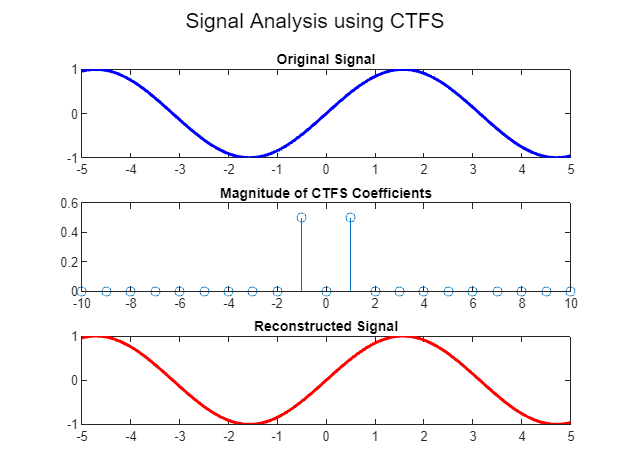

syms t ak;

T = 2*pi;
w = (2*pi)/T;
x = sin(t);
ak = CTFS(x, T);
x1 = ICTFS(ak, T);

figure;
subplot(3,1,1);
fplot(x, 'blue', 'linewidth', 2);
title('Original Signal');

subplot(3,1,2);
stem(-10:10, abs(ak));
title('Magnitude of CTFS Coefficients');

subplot(3,1,3);
fplot(x1, 'r', 'linewidth', 2);
title('Reconstructed Signal');

sgtitle('Signal Analysis using CTFS');

### Task 2 

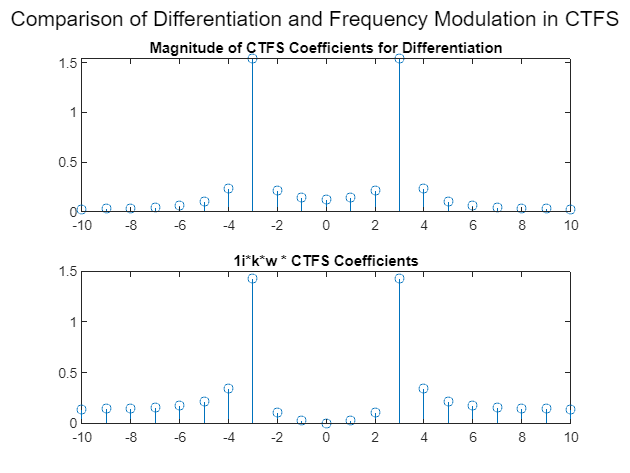

syms t;

x = sin(pi*t);
T = 2*pi;
k = -10:10;
w = (2*pi)/T;

Dif = diff(x, t);

figure;

LHS = CTFS(Dif, T);
subplot(2,1,1);
stem(k, abs(LHS));
title('Magnitude of CTFS Coefficients for Differentiation');

ak = CTFS(x, T);
RHS = (1i*k*w .* ak);
subplot(2,1,2);
stem(k, abs(RHS));
title('1i*k*w * CTFS Coefficients');

sgtitle('Comparison of Differentiation and Frequency Modulation in CTFS');

#### Function 1 

function ak = CTFS(x, T)
    syms t;
    w = (2*pi)/T;
    
    ak = zeros(1, 21);  % Initializing ak to zeros
    
    for k = -10:10
        ak(k+11) = (1/T) * int(x * exp(-1i*k*w*t), t, 0, T);
    end
end

#### Function 2 

function x = ICTFS(ak, T)
    syms t;
    w = (2*pi)/T;

    x = 0;
    for k = -10:10
        x = x + ak(k+11) * exp(1j*k*w*t);
    end
end